%  0 - 60, 0 - 45, 0 - 30 | step size = 5
% 100 points from 0-60, -45, 0-30 such that those points are linear 
% second order curve 
% Curve Fitting
% comparison of theta1 , theta2 and theta3 in a plot
%k=0.6

T01 = get_DH_matrix(a1,0,0,theta1);
T12 = get_DH_matrix(0,deg2rad(90),0,deg2rad(90)+theta2);
T23 = get_DH_matrix(0,0,d3,theta3);
T_eef = T01*T12*T23;
disp(T_eef)

$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{3}\right)\,\sigma_{2}-\sin\left(\theta_{3}\right)\,\sigma_{4} & -\sin\left(\theta_{3}\right)\,\sigma_{2}-\cos\left(\theta_{3}\right)\,\sigma_{4} & \sigma_{1} & d_{3}\,\sigma_{1}+a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{3}\right)\,\sigma_{3}+\cos\left(\theta_{3}\right)\,\sigma_{1} & \cos\left(\theta_{3}\right)\,\sigma_{3}-\sin\left(\theta_{3}\right)\,\sigma_{1} & \sin\left(\theta_{1}\right)\,\sigma_{5}-\cos\left(\theta_{1}\right)\,\sigma_{6} & a_{1}\,\sin\left(\theta_{1}\right)-d_{3}\,\sigma_{2}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & \frac{4967757600021511}{81129638414606681695789005144064} & \frac{4967757600021511\,d_{3}}{81129638414606681695789005144064}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\sigma_{5}+\sigma_{6}\,\sin\left(\theta_{1}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\sigma_{6}-\sin\left(\theta_{1}\right)\,\sigma_{5}\\ \sigma_{3}=\frac{4967757600021511\,\cos\left(\theta_{1}\right)\,\sigma_{6}}{81129638414606681695789005144064}-\frac{4967757600021511\,\sin\left(\theta_{1}\right)\,\sigma_{5}}{81129638414606681695789005144064}\\ \sigma_{4}=\frac{4967757600021511\,\cos\left(\theta_{1}\right)\,\sigma_{5}}{81129638414606681695789005144064}+\frac{4967757600021511\,\sigma_{6}\,\sin\left(\theta_{1}\right)}{81129638414606681695789005144064}\\ \sigma_{5}=\sin\left(\theta_{2}+\frac{\pi }{2}\right)\\ \sigma_{6}=\cos\left(\theta_{2}+\frac{\pi }{2}\right) \end{array}$$


tool_x = [];
tool_y = [];
tool_z = [];
j1 = [];
j2 = [];
j3 = [];

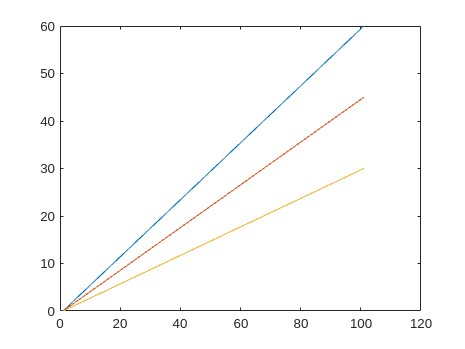

theta1_var = [];
theta2_var= [];
theta3_var= [];

for i = 0:60/100:60
    theta1_var = [theta1_var i];
end
for i = 0:45/100:45
    theta2_var = [theta2_var i];
end
for i = 0:30/100:30
    theta3_var = [theta3_var i];
end

plot(theta1_var);
hold("on");
plot(theta2_var);
plot(theta3_var);
hold('off');

for i = 1:1:100
    t1 = theta1_var(i);
    t2 = theta2_var(i);
    t3 = theta3_var(i);
    tf = subs(T_eef,[a1,d3,theta1,theta2,theta3],[100,30,deg2rad(t1),deg2rad(t2),deg2rad(t3)]);
    tool_x = [tool_x tf(1,4)];
    tool_y = [tool_y tf(2,4)];
    tool_z = [tool_z tf(3,4)];
end
disp('done');

done


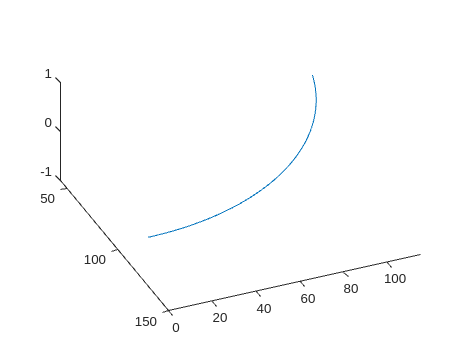

plot3(tool_x,tool_y,tool_z)

tf1 = T01;
tf2 = T01*T12;
tf3 = tf2*T03;


function T = get_DH_matrix(a,alpha,d,theta)
T = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha)  a*cos(theta)
     sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta)
     0 sin(alpha) cos(alpha) d
     0 0 0 1];
end